# Compute the Finite Difference Stencils

This **function** computes the Finite Difference stencils for our House insulation analysis.  The naming convention for the nodes and Control surface faces is summarised below, where:

- ${\dot{Q} }_N \;\;,\;\;{\dot{Q} }_S \;\;,\;{\dot{Q} }_E \;\;,\;{\dot{Q} }_W$ represent **CONDUCTION** heat flow into the target node

- ${\dot{Q} }_{N\;\;}$represents heat flow through the **NORTH** face 

- ${\dot{Q} }_{\mathrm{NC}} \;\;,\;\;{\dot{Q} }_{\mathrm{SC}} \;\;,\;{\dot{Q} }_{\mathrm{EC}} \;\;,\;{\dot{Q} }_{\mathrm{WC}}$ represent **CONVECTION** heat flow into the target node

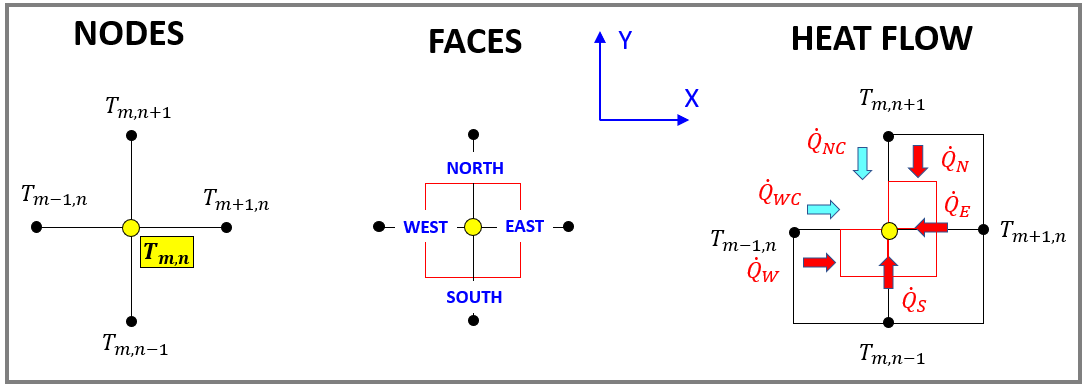

For our specific problem there are approximately 2 dozen different NODE types.  These different NODE types have been given the labels defined in [bh_fd_node_type_ENUM](matlab:  edit bh_fd_node_type_ENUM).  Diagrams for these different NODE types are included in the analysis subfunctions defined in this file, eg: HERE.  For each NODE type we conduct a **Steady State** thermal analysis of the appropriate Control Surface, eg:

- 
$$0=\;{\dot{Q} }_{N\;\;\;} +\;\;{\dot{Q} }_S \;+\;\;{\dot{Q} }_E \;+\;{\dot{Q} }_W \;\;\;+\;\;\;{\dot{Q} }_{\mathrm{NC}} \;\;,\;\;{\dot{Q} }_{\mathrm{SC}} \;\;,\;{\dot{Q} }_{\mathrm{EC}} \;\;,\;{\dot{Q} }_{\mathrm{WC}}$$


For each NODE type we rearrange the above Heat equation into the form:

- 
$$A\;\ldotp x=b$$
 

where:      $x^T =\left\lbrack \begin{array}{ccccccccc}
T_{m-1,n+1}  & T_{m,n+1}  & T_{m+1,n+1}  & T_{m-1,n}  & T_{m,n}  & T_{m+1,n}  & T_{m-1,n-1}  & T_{m,n-1}  & T_{m+1,n-1} 
\end{array}\right\rbrack$

**NOTE:   **Symbolic AND Numeric versions of the $A\;,\;x\;,\;b$ matrices are returned in our function output table for each different NODE type

## Function INPUTS

- `my_params` : an instance of the [bh_sys_params_CLS](matlab: edit bh_sys_params_CLS) class. It contains the thermal parameters for our system

## Function OUTPUTS

- `sten_TAB` : a table.  Thsi table has been configured such that the NODE type can be used as a ROW index

The `sten_TAB` has the following columns:

-  `node_type_fd  :` a string label for the NODE type. It will be one of the labels defined in [bh_fd_node_type_ENUM](matlab:  edit bh_fd_node_type_ENUM)

- ` s_A           :` a symbolic version of the $A$matrix for that NODE type  

- ` s_b           :` a symbolic version of the $b$matrix for that NODE type   

- ` s_x           :` a $1\times 9$ symbolic array of the symbols $\left\lbrack \begin{array}{ccccccccc}
T_{m-1,n+1}  & T_{m,n+1}  & T_{m+1,n+1}  & T_{m-1,n}  & T_{m,n}  & T_{m+1,n}  & T_{m-1,n-1}  & T_{m,n-1}  & T_{m+1,n-1} 
\end{array}\right\rbrack$   

- ` str_x         :` a $1\times 9$ string array of the symbols      $\left\lbrack \begin{array}{ccccccccc}
T_{m-1,n+1}  & T_{m,n+1}  & T_{m+1,n+1}  & T_{m-1,n}  & T_{m,n}  & T_{m+1,n}  & T_{m-1,n-1}  & T_{m,n-1}  & T_{m+1,n-1} 
\end{array}\right\rbrack$   

- ` T_mM1_nP1     :`  a numeric value corresponding to $A_1$    

- ` T_m_nP1       : `a numeric value corresponding to $A_2$  

- ` T_mP1_nP1     : `a numeric value corresponding to $A_3$  

- ` T_mM1_n       : `a numeric value corresponding to $A_4$  

- ` T_m_n         : `a numeric value corresponding to $A_5$  

- ` T_mP1_n       : `a numeric value corresponding to $A_6$  

- ` T_mM1_nM1     : `a numeric value corresponding to $A_7$  

- ` T_m_nM1       : `a numeric value corresponding to $A_8$  

- ` T_mP1_nM1     : `a numeric value corresponding to $A_9$  

- ` b             : `a numeric value corresponding to $b$  

## History

- `19-Jul-2021 : created (bhorton@mathworks.com)`

function sten_TAB = bh_get_node_stencils(my_params)
    arguments
        my_params (1,1) bh_sys_params_CLS
    end
    
    sten_TAB = LOC_get_stencils(my_params);
end

# **General stencil for calc for Blocks B and C**

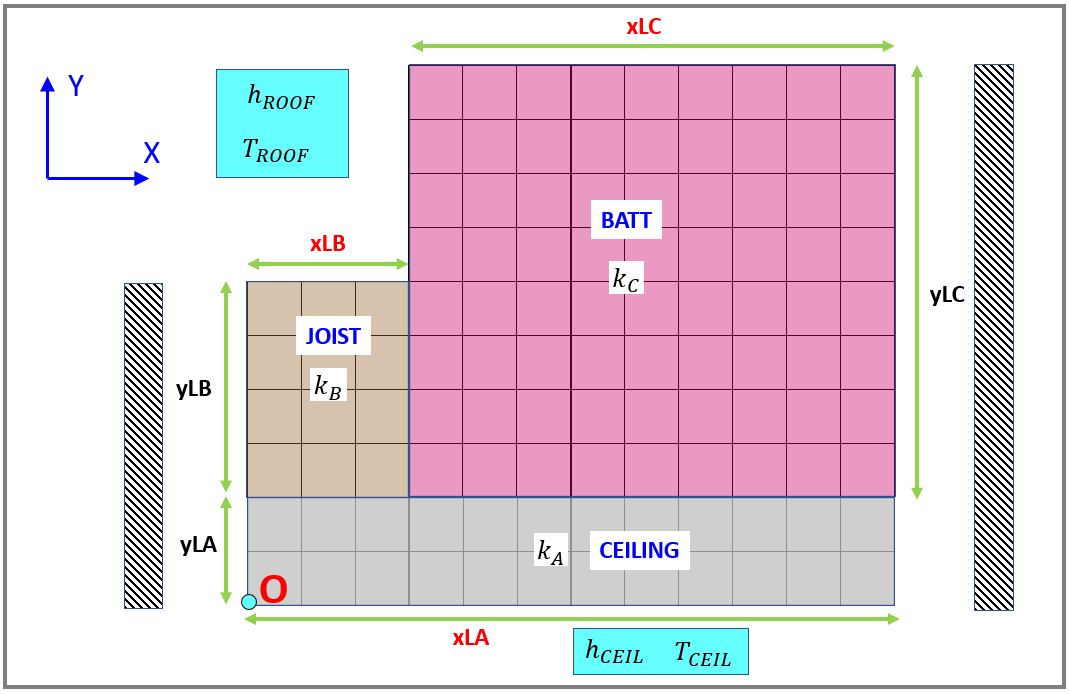

function [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d)
  bh_symbol_DEFS                          
  
  [A_N,  A_S , A_E , A_W ] = deal(A_cond(1), A_cond(2), A_cond(3), A_cond(4) ); % CONDUCTION Areas  
  [A_NC, A_SC, A_EC, A_WC] = deal(A_conv(1), A_conv(2), A_conv(3), A_conv(4) ); % CONVECTION Areas
  [k_N , k_S , k_E , k_W ] = deal(     k(1),      k(2),      k(3),      k(4) ); % k
  [d_N , d_S,  d_E , d_W ] = deal(     d(1),      d(2),      d(3),      d(4) ); % d
  
  Q_NC = h_ROOF * A_NC * (T_ROOF - T_m_n);
  Q_SC = h_ROOF * A_SC * (T_ROOF - T_m_n);
  Q_EC = h_ROOF * A_EC * (T_ROOF - T_m_n);
  Q_WC = h_ROOF * A_WC * (T_ROOF - T_m_n);
  
  Q_N =     k_N * A_N * (T_NORTH - T_m_n) / d_N; 
  Q_S =     k_S * A_S * (T_SOUTH - T_m_n) / d_S; 
  Q_E =     k_E * A_E * (T_EAST  - T_m_n) / d_E; 
  Q_W =     k_W * A_W * (T_WEST  - T_m_n) / d_W;  
  
  Q_eq = 0 == (Q_NC + Q_SC + Q_EC + Q_WC +    Q_N + Q_S + Q_E + Q_W);
  
      x  = LOC_T_vars;
  [A, b] = equationsToMatrix(Q_eq, x);
    
end

# **General stencil for calc for Block A**

function [A, b, x] = LOC_stenc_calc_BLK_A(A_cond, A_conv, k, d)
  bh_symbol_DEFS                          
  
  [A_N,  A_S , A_E , A_W ] = deal(A_cond(1), A_cond(2), A_cond(3), A_cond(4) ); % CONDUCTION Areas  
  [A_NC, A_SC, A_EC, A_WC] = deal(A_conv(1), A_conv(2), A_conv(3), A_conv(4) ); % CONVECTION Areas
  [k_N , k_S , k_E , k_W ] = deal(     k(1),      k(2),      k(3),      k(4) ); % k
  [d_N , d_S,  d_E , d_W ] = deal(     d(1),      d(2),      d(3),      d(4) ); % d
  
  Q_NC = h_CEIL * A_NC * (T_CEIL - T_m_n);
  Q_SC = h_CEIL * A_SC * (T_CEIL - T_m_n);
  Q_EC = h_CEIL * A_EC * (T_CEIL - T_m_n);
  Q_WC = h_CEIL * A_WC * (T_CEIL - T_m_n);
  
  Q_N =     k_N * A_N * (T_NORTH - T_m_n) / d_N; 
  Q_S =     k_S * A_S * (T_SOUTH - T_m_n) / d_S; 
  Q_E =     k_E * A_E * (T_EAST  - T_m_n) / d_E; 
  Q_W =     k_W * A_W * (T_WEST  - T_m_n) / d_W;  
  
  Q_eq = 0 == (Q_NC + Q_SC + Q_EC + Q_WC +    Q_N + Q_S + Q_E + Q_W);
  
      x  = LOC_T_vars;
  [A, b] = equationsToMatrix(Q_eq, x);
    
end

# **Our Stencil table**

function my_tab = LOC_get_stencils(my_params)
    my_lookup = { ...    
        bh_fd_node_type_ENUM.G_BLK_B_INTERNAL, @LOC_G_BLK_B_INTERNAL  ;
        bh_fd_node_type_ENUM.G_BLK_B_NW      , @LOC_G_BLK_B_NW        ;
        bh_fd_node_type_ENUM.G_BLK_B_N       , @LOC_G_BLK_B_N         ;
        bh_fd_node_type_ENUM.G_BLK_B_NE      , @LOC_G_BLK_B_NE        ;
        bh_fd_node_type_ENUM.G_BLK_B_E       , @LOC_G_BLK_B_E         ;
        bh_fd_node_type_ENUM.G_BLK_B_SE      , @LOC_G_BLK_B_SE        ;
        bh_fd_node_type_ENUM.G_BLK_B_S       , @LOC_G_BLK_B_S         ;
        bh_fd_node_type_ENUM.G_BLK_B_SW      , @LOC_G_BLK_B_SW        ;
        bh_fd_node_type_ENUM.G_BLK_B_W       , @LOC_G_BLK_B_W         ;
        %----------------------------------------------------------------
        bh_fd_node_type_ENUM.G_BLK_C_INTERNAL, @LOC_G_BLK_C_INTERNAL  ;
        bh_fd_node_type_ENUM.G_BLK_C_W       , @LOC_G_BLK_C_W         ;
        bh_fd_node_type_ENUM.G_BLK_C_NW      , @LOC_G_BLK_C_NW        ;
        bh_fd_node_type_ENUM.G_BLK_C_N       , @LOC_G_BLK_C_N         ;
        bh_fd_node_type_ENUM.G_BLK_C_NE      , @LOC_G_BLK_C_NE        ;
        bh_fd_node_type_ENUM.G_BLK_C_E       , @LOC_G_BLK_C_E         ;
        bh_fd_node_type_ENUM.G_BLK_C_SE      , @LOC_G_BLK_C_SE        ;
        bh_fd_node_type_ENUM.G_BLK_C_S       , @LOC_G_BLK_C_S         ;
        %----------------------------------------------------------------        
        bh_fd_node_type_ENUM.G_BLK_A_INTERNAL, @LOC_G_BLK_A_INTERNAL  ;
        bh_fd_node_type_ENUM.G_BLK_A_SW      , @LOC_G_BLK_A_SW        ;
        bh_fd_node_type_ENUM.G_BLK_A_W       , @LOC_G_BLK_A_W         ;
        bh_fd_node_type_ENUM.G_BLK_A_S       , @LOC_G_BLK_A_S         ;
        bh_fd_node_type_ENUM.G_BLK_A_SE      , @LOC_G_BLK_A_SE        ;
        bh_fd_node_type_ENUM.G_BLK_A_E       , @LOC_G_BLK_A_E         ;
    };

    [num_node_types, ~] = size(my_lookup);
       
    my_tab = table();
    my_tab.node_type_fd = strings(num_node_types,1);
    my_tab.s_A           = repmat( {sym(0)}, num_node_types,1);
    my_tab.s_b           = repmat( {sym(0)}, num_node_types,1);    
    my_tab.s_x           = repmat( {sym(0)}, num_node_types,1);   
    my_tab.str_x         = repmat( {strings(1,9)}, num_node_types,1);
    
    my_tab.T_mM1_nP1     = zeros(num_node_types,1);
    my_tab.T_m_nP1       = zeros(num_node_types,1);
    my_tab.T_mP1_nP1     = zeros(num_node_types,1);
    
    my_tab.T_mM1_n       = zeros(num_node_types,1);
    my_tab.T_m_n         = zeros(num_node_types,1);
    my_tab.T_mP1_n       = zeros(num_node_types,1);
    
    my_tab.T_mM1_nM1     = zeros(num_node_types,1);
    my_tab.T_m_nM1       = zeros(num_node_types,1);
    my_tab.T_mP1_nM1     = zeros(num_node_types,1);
    my_tab.b             = zeros(num_node_types,1);    
    
    
    for kk = 1:num_node_types
    
        fh         = my_lookup{kk,2};        
        [A, b, x]  = fh();
        
        
        my_tab.node_type_fd(kk) = string(my_lookup{kk,1});
        my_tab.s_A(kk)           = {A};
        my_tab.s_b(kk)           = {b};    
        my_tab.s_x(kk)           = {x};
        
        my_tab.str_x(kk)         = {string(x)};
        
        tmp_A = LOC_eval_to_numeric(A, my_params);
        tmp_b = LOC_eval_to_numeric(b, my_params);
        
        my_tab.b(kk) = tmp_b;
        
        for zz=1:length(x)
             THE_VAR     = x(zz);
             THE_VAR_str = string(THE_VAR);
             
             my_tab{kk, THE_VAR_str} = tmp_A(zz);            
        end
        
        fprintf("\n ... Finished [%2d] of %2d :  NODE_TYPE = %s", kk,num_node_types,my_tab.node_type_fd(kk) );
    end % for kk = 1:num_node_type
    
    % allow the table ROW index to be the NODE_STR
    my_tab.Properties.RowNames = my_tab.node_type_fd;
    
end

Compute Numeric values for Symbolic expressions

function out = LOC_eval_to_numeric(sym_exp, params_S)
    
    % load symbolic variables
    bh_symbol_DEFS
    
    p           = params_S;    
    sym_list    = [  k_A,    k_B,      k_C,    Delta_X,    Delta_Y,   h_ROOF,   h_CEIL,   T_ROOF,   T_CEIL];
    num_list    = [p.k_A,  p.k_B,    p.k_C,  p.Delta_X,  p.Delta_Y, p.h_ROOF, p.h_CEIL, p.T_ROOF, p.T_CEIL];

    new_sym_exp = subs(sym_exp, sym_list, num_list);    
    out         = double(new_sym_exp);    
end

# **Utilities**

Specifying the **Area** of a FACE of a control surface

function [N_A, S_A, E_A, W_A] = LOC_get_A_NSEW(N,S,E,W)
    arguments
        N (1,1) string {mustBeMember(N, ["N_0","N_HALF","N_FULL"])}
        S (1,1) string {mustBeMember(S, ["S_0","S_HALF","S_FULL"])}
        E (1,1) string {mustBeMember(E, ["E_0","E_HALF","E_FULL"])}
        W (1,1) string {mustBeMember(W, ["W_0","W_HALF","W_FULL"])}    
    end
    
    bh_symbol_DEFS
    
    [N_A, S_A, E_A, W_A] = deal( sym(0),  sym(0),  sym(0),  sym(0) );
    
    switch N
        case "N_HALF"
                      N_A = Delta_X/2;
        case "N_FULL"
                      N_A = Delta_X;
    end
    
    switch S
        case "S_HALF"
                      S_A = Delta_X/2;
        case "S_FULL"
                      S_A = Delta_X;
    end        

    switch E
        case "E_HALF"
                      E_A = Delta_Y/2;
        case "E_FULL"
                      E_A = Delta_Y;
    end 
    
    switch W
        case "W_HALF"
                      W_A = Delta_Y/2;
        case "W_FULL"
                      W_A = Delta_Y;
    end            
end

Specifying the DISTANCE travelled by Q passing through  FACE N or S or E or W

function [N_d, S_d, E_d, W_d] = LOC_get_d_NSEW(N,S,E,W)
    arguments
        N (1,1) string {mustBeMember(N, ["N_0", "N_FULL"])}
        S (1,1) string {mustBeMember(S, ["S_0", "S_FULL"])}
        E (1,1) string {mustBeMember(E, ["E_0", "E_FULL"])}
        W (1,1) string {mustBeMember(W, ["W_0", "W_FULL"])}    
    end
    
    bh_symbol_DEFS
    
    [N_d, S_d, E_d, W_d] = deal( sym(0),  sym(0),  sym(0),  sym(0) );
    
    switch N
        case "N_FULL"
                      N_d = Delta_Y;
    end
    
    switch S
        case "S_FULL"
                      S_d = Delta_Y;
    end        

    switch E
        case "E_FULL"
                      E_d = Delta_X;
    end 
    
    switch W
        case "W_FULL"
                      W_d = Delta_X;
    end            
end

A list of Temperatures

function T_list = LOC_T_vars()

    bh_symbol_DEFS

    T_list = [T_mM1_nP1, T_m_nP1,  T_mP1_nP1, ...
              T_mM1_n,   T_m_n,    T_mP1_n, ...
              T_mM1_nM1, T_m_nM1,  T_mP1_nM1 ];

end

# **B-block node types**

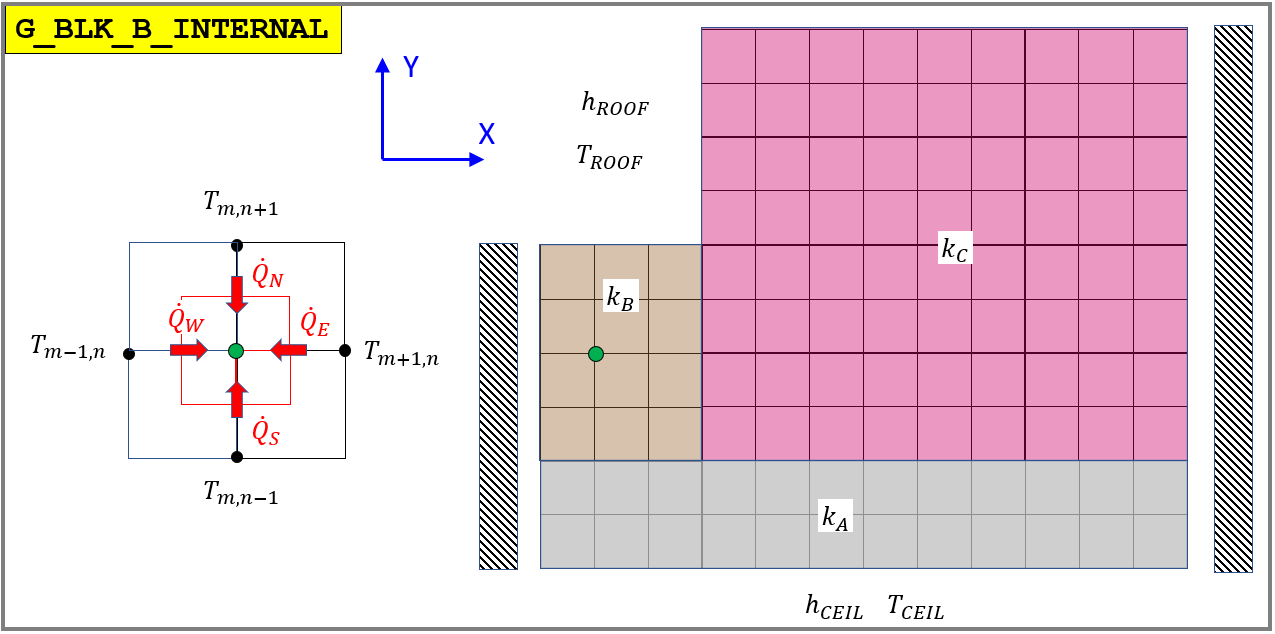

function [A, b, x]  = LOC_G_BLK_B_INTERNAL()
  %Load symbolic symbols
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",    "S_0"   , "E_0"   , "W_0"); % Convection Areas
  [A_N , A_S , A_E , A_W ] = LOC_get_A_NSEW("N_FULL", "S_FULL", "E_FULL", "W_FULL"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_B ,     k_B,      k_B,      k_B);
  
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

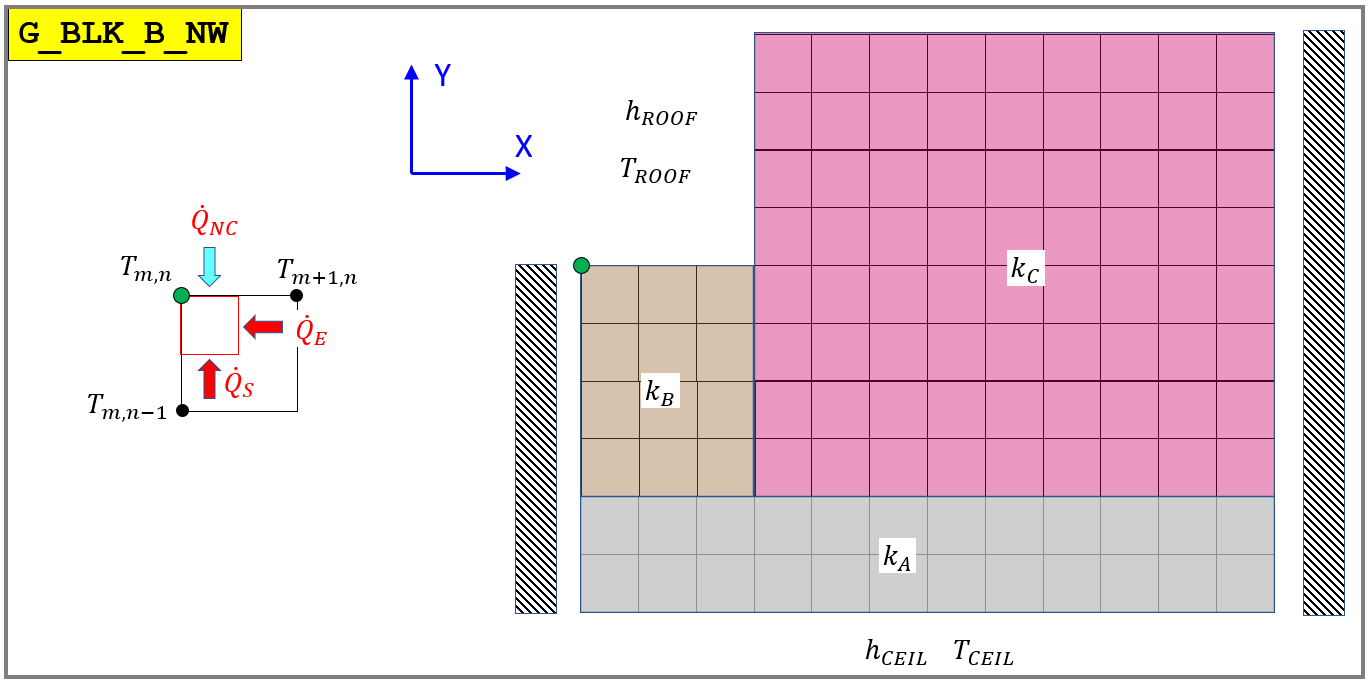

function [A, b, x]  = LOC_G_BLK_B_NW()
  %Load symbolic symbols
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_HALF", "S_0"   , "E_0"   , "W_0"); % Convection Areas
  [A_N , A_S , A_E , A_W ] = LOC_get_A_NSEW("N_0"   , "S_HALF", "E_HALF", "W_0"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( sym(0) ,   k_B,      k_B,    sym(0));
  
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

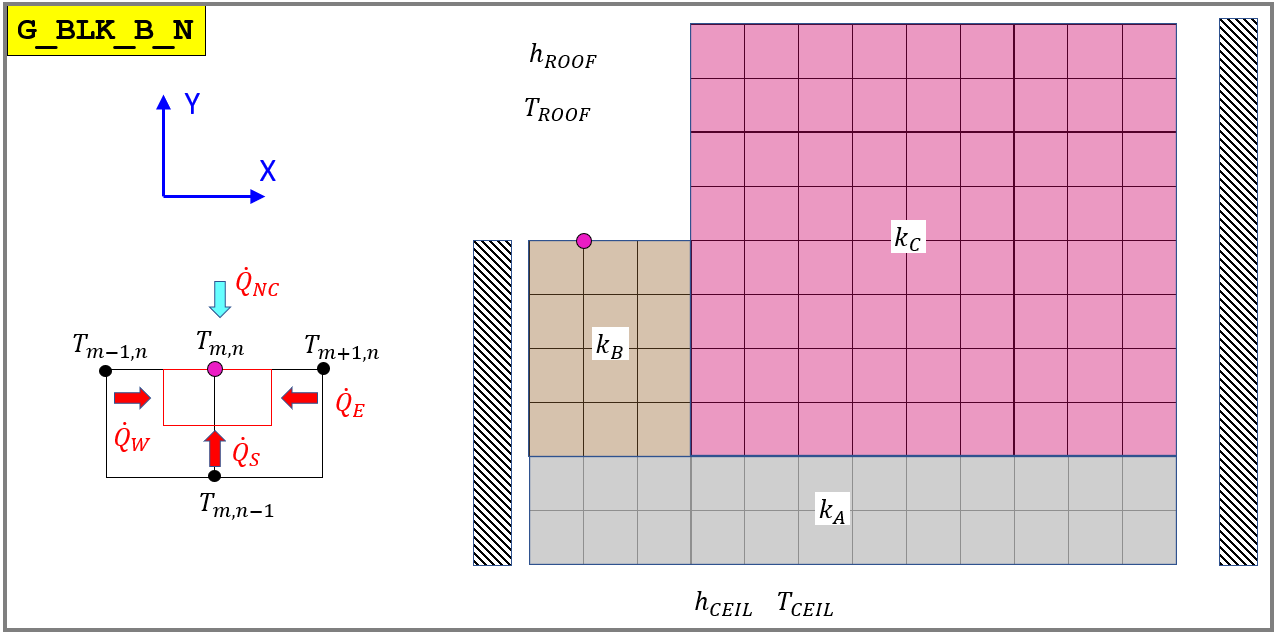

function [A, b, x]  = LOC_G_BLK_B_N()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_FULL", "S_0"   , "E_0"   , "W_0"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_0"   , "S_FULL", "E_HALF", "W_HALF"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( sym(0),    k_B,      k_B,      k_B);
  
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

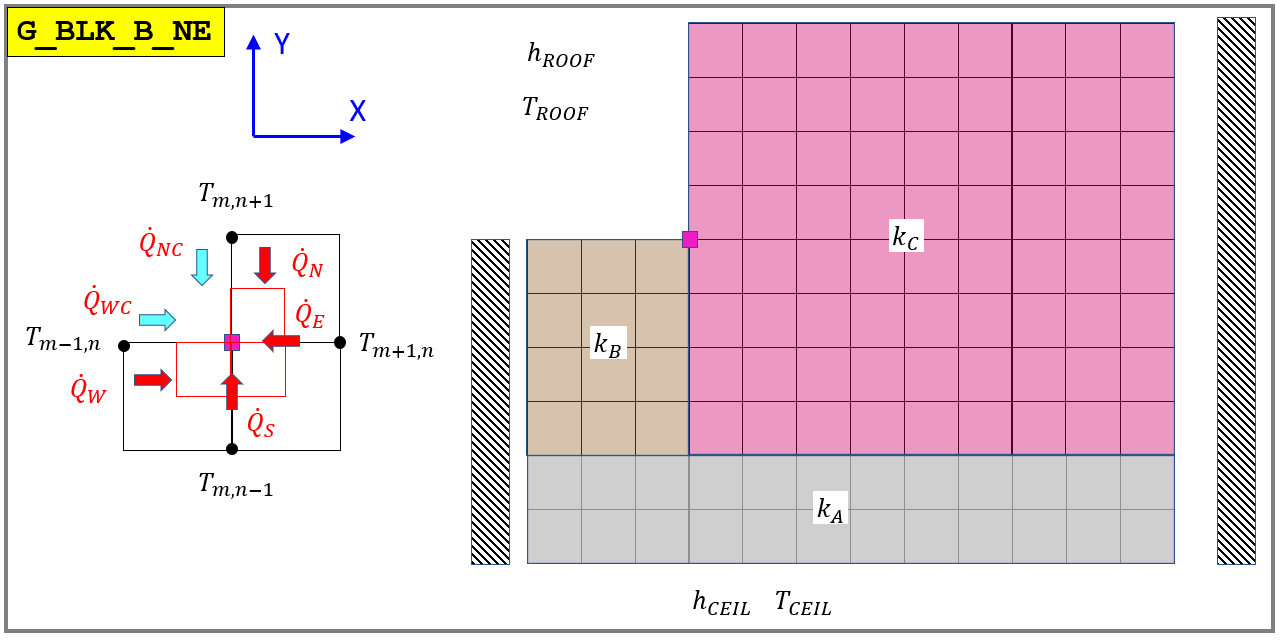

function [A, b, x]  = LOC_G_BLK_B_NE()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_HALF", "S_0"   , "E_0"   , "W_HALF"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_HALF", "S_FULL", "E_FULL", "W_HALF"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_C,      k_C,      k_C,      k_B);
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

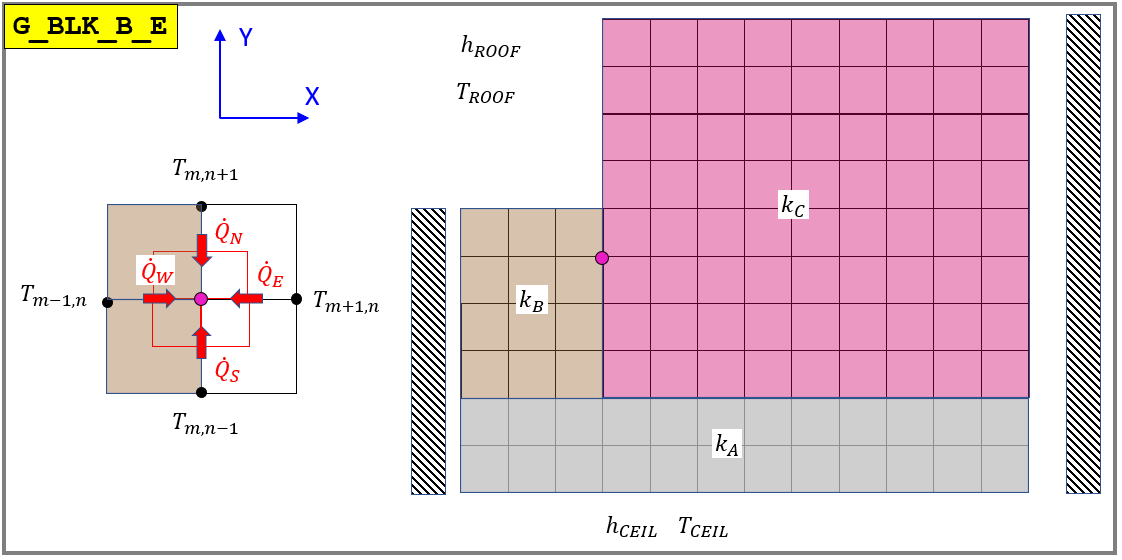

function [A, b, x]  = LOC_G_BLK_B_E()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",    "S_0"   , "E_0"   , "W_0"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_FULL", "S_FULL", "E_FULL", "W_FULL"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_C,      k_C,      k_C,      k_B);
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

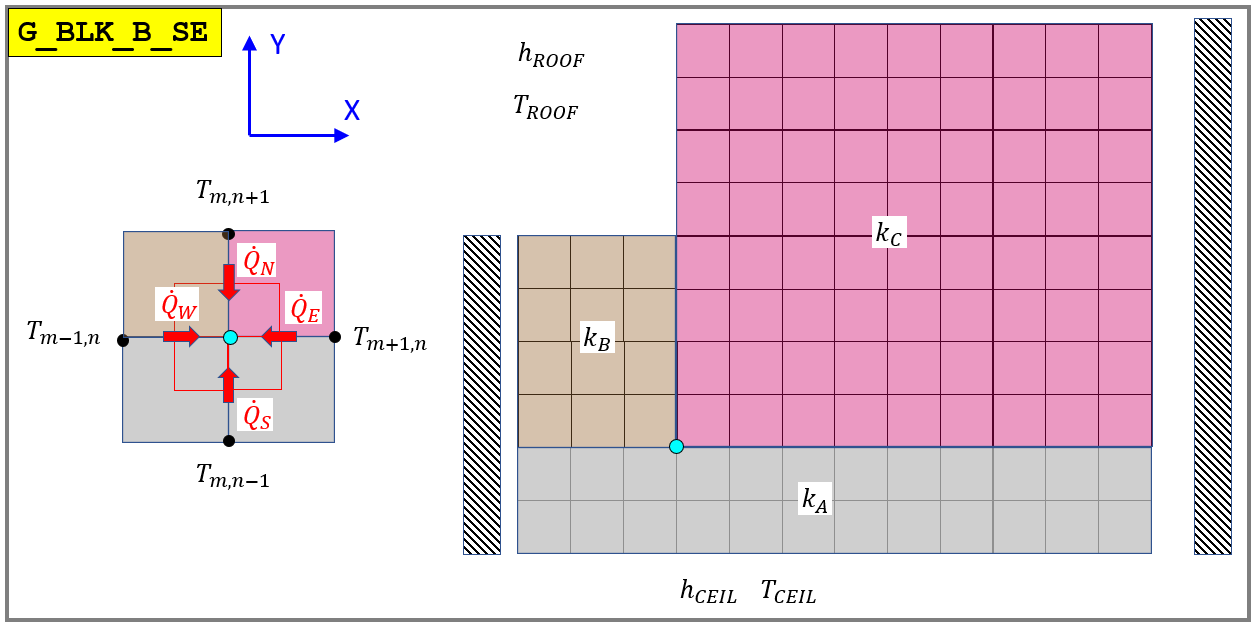

function [A, b, x]  = LOC_G_BLK_B_SE()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",    "S_0"   , "E_0"   , "W_0"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_FULL", "S_FULL", "E_FULL", "W_FULL"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_C,      k_A,      k_C,      k_B);
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

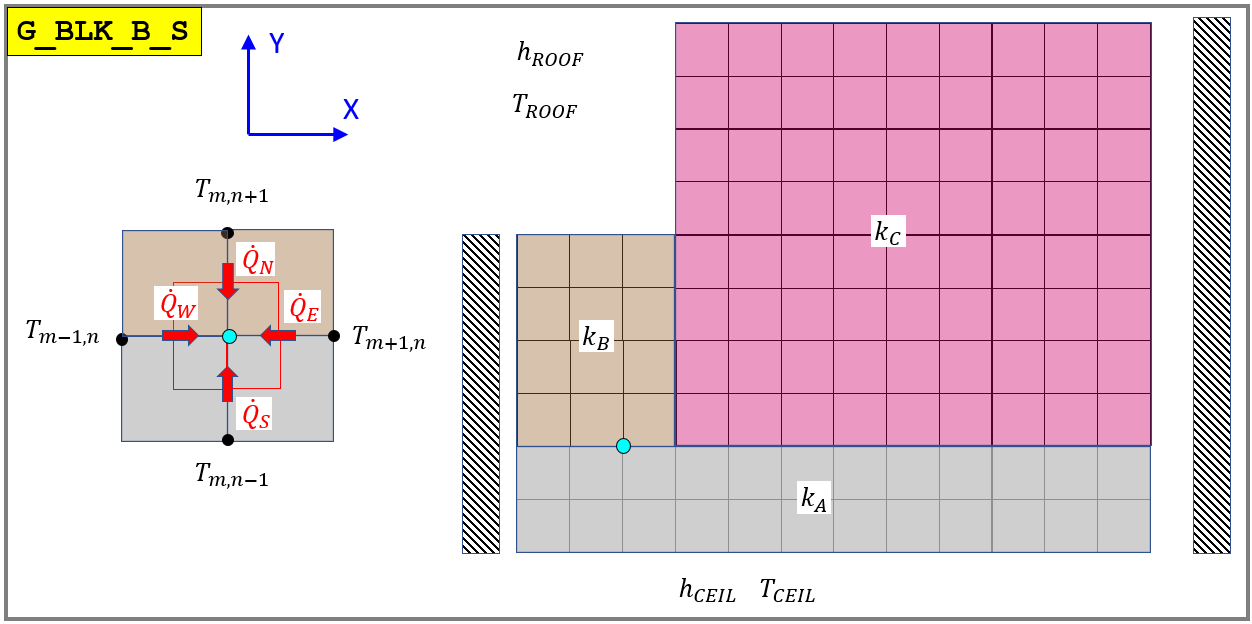

function [A, b, x]  = LOC_G_BLK_B_S()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",    "S_0"   , "E_0"   , "W_0"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_FULL", "S_FULL", "E_FULL", "W_FULL"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_B,      k_A,      k_B,      k_B);
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

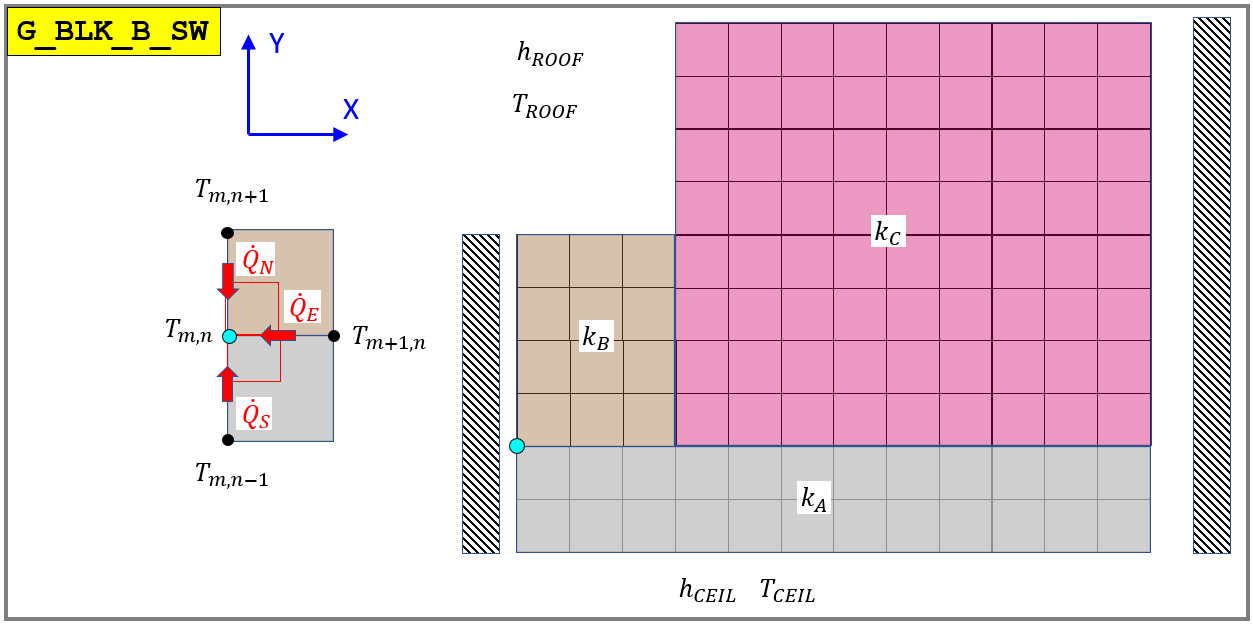

function [A, b, x]  = LOC_G_BLK_B_SW()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",    "S_0"   , "E_0"   , "W_0"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_HALF", "S_HALF", "E_FULL", "W_0"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_B,      k_A,      k_B,     sym(0));
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

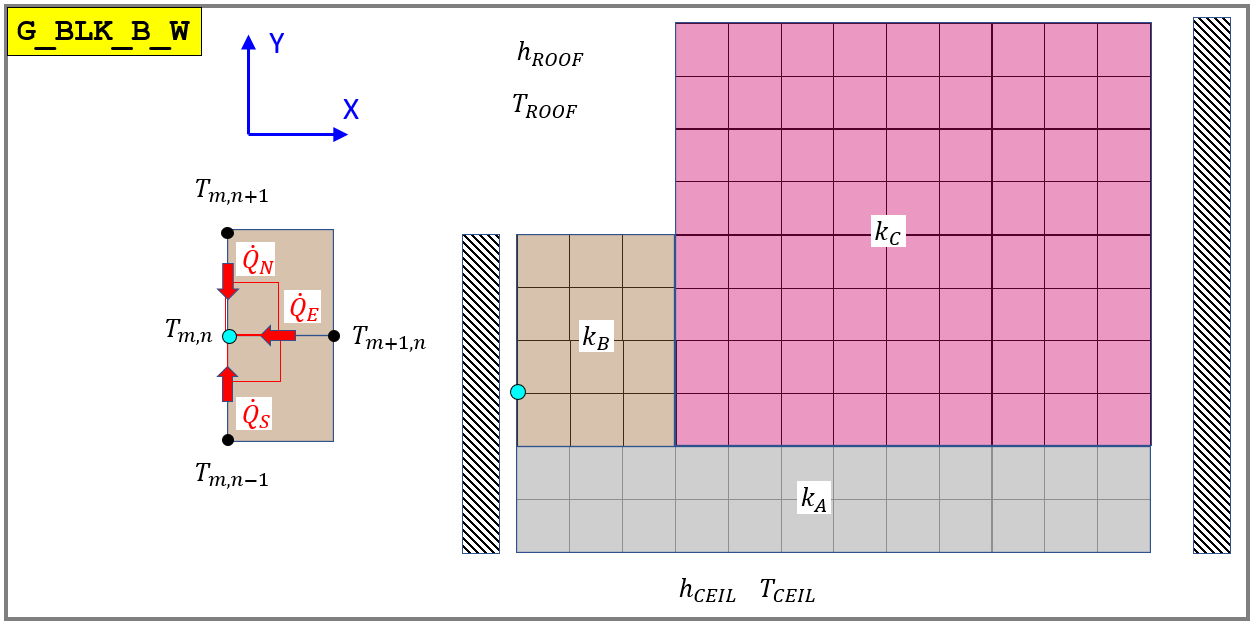

function [A, b, x]  = LOC_G_BLK_B_W()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",    "S_0"   , "E_0"   , "W_0"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_HALF", "S_HALF", "E_FULL", "W_0"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_B,      k_B,      k_B,     sym(0));
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

# **C-block node types**

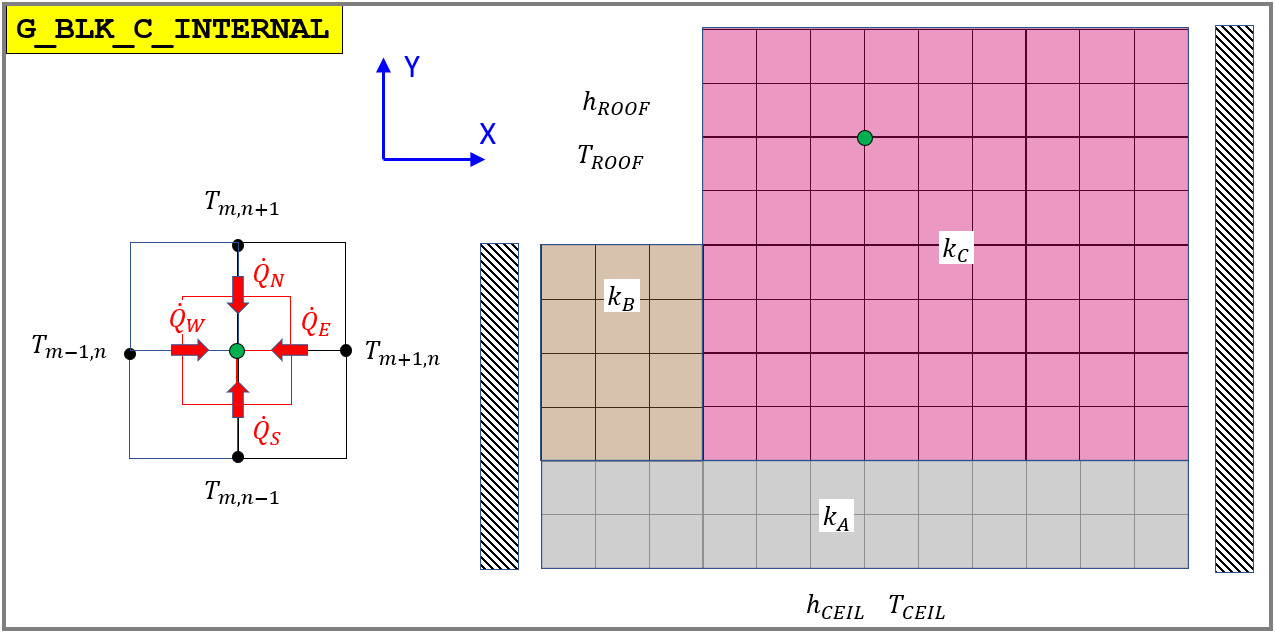

function [A, b, x]  = LOC_G_BLK_C_INTERNAL()
  %Load symbolic symbols
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",    "S_0"   , "E_0"   , "W_0"); % Convection Areas
  [A_N , A_S , A_E , A_W ] = LOC_get_A_NSEW("N_FULL", "S_FULL", "E_FULL", "W_FULL"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_C ,     k_C,      k_C,      k_C);
  
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

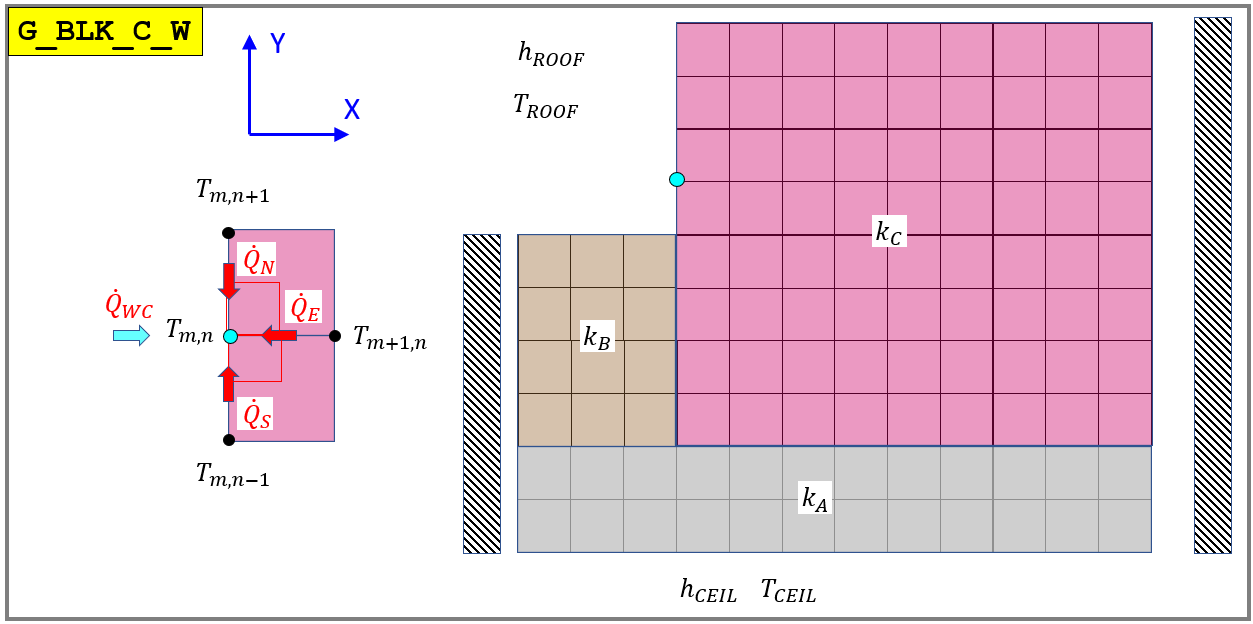

function [A, b, x]  = LOC_G_BLK_C_W()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",    "S_0"   , "E_0"   , "W_FULL"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_HALF", "S_HALF", "E_FULL", "W_0"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_C,      k_C,      k_C,     sym(0));
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

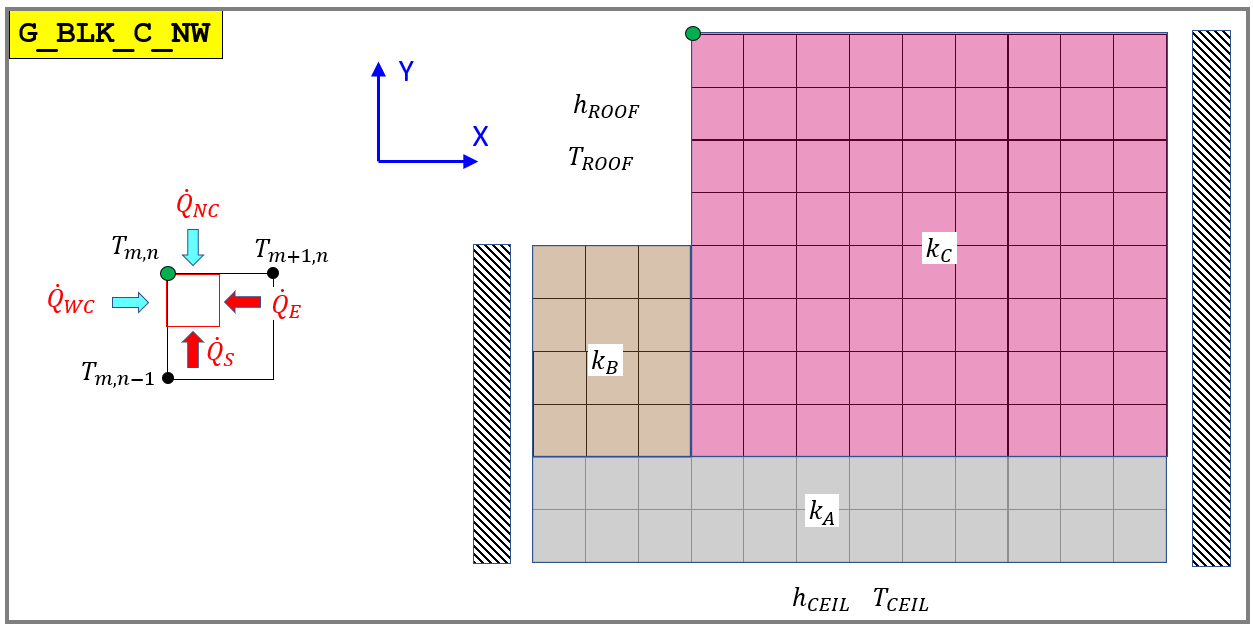

function [A, b, x]  = LOC_G_BLK_C_NW()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_HALF",  "S_0"   , "E_0"   , "W_HALF"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_0",     "S_HALF", "E_HALF", "W_0"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( sym(0),    k_C,      k_C,     sym(0));
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

# 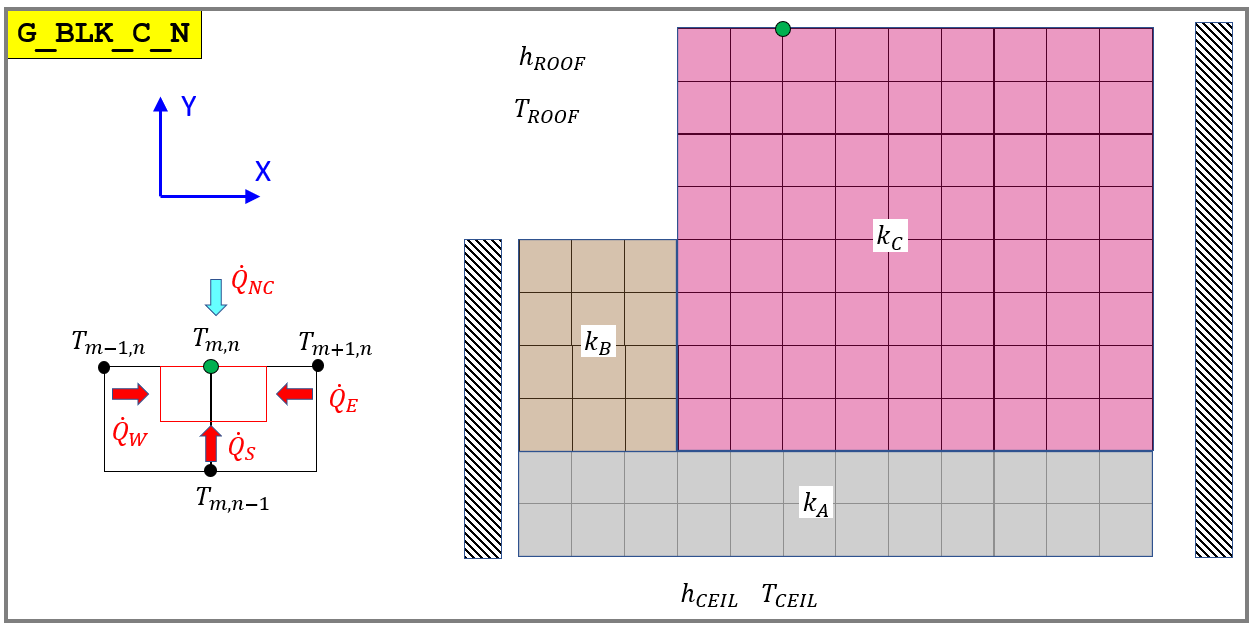

function [A, b, x]  = LOC_G_BLK_C_N()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_FULL",  "S_0"   , "E_0"   , "W_0"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_0",     "S_FULL", "E_HALF", "W_HALF"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( sym(0),    k_C,      k_C,     k_C);
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

# 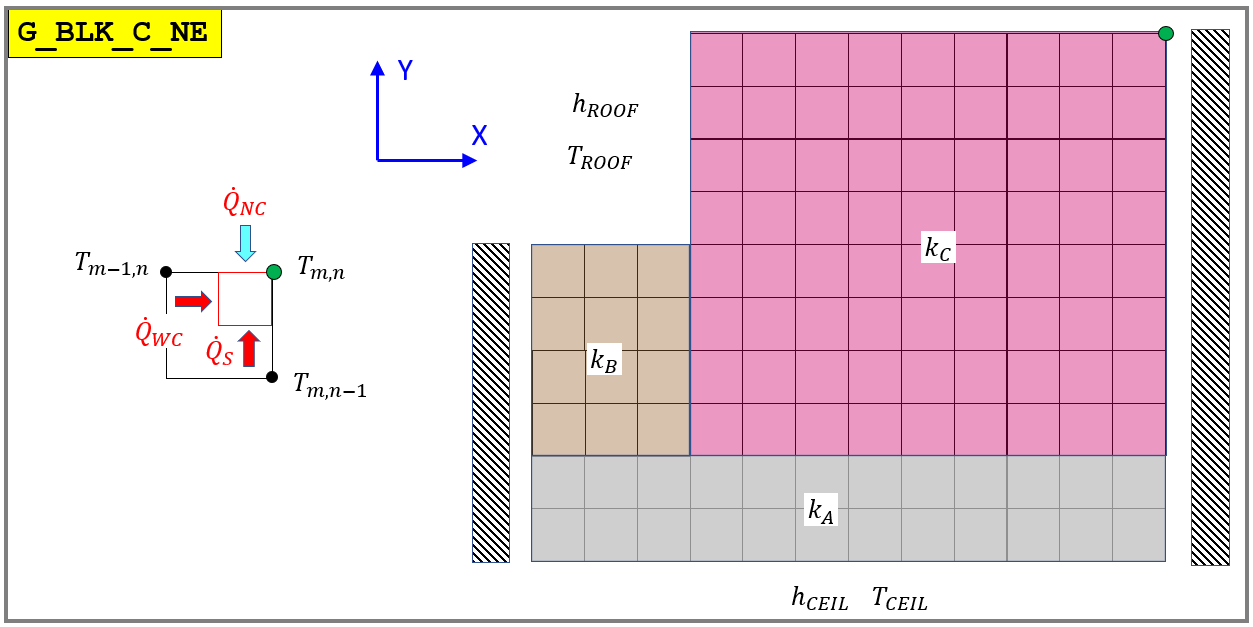

function [A, b, x]  = LOC_G_BLK_C_NE()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_HALF",  "S_0"   , "E_0"   , "W_0"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_0",     "S_HALF", "E_0", "W_HALF"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( sym(0),    k_C,    sym(0),    k_C);
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

# 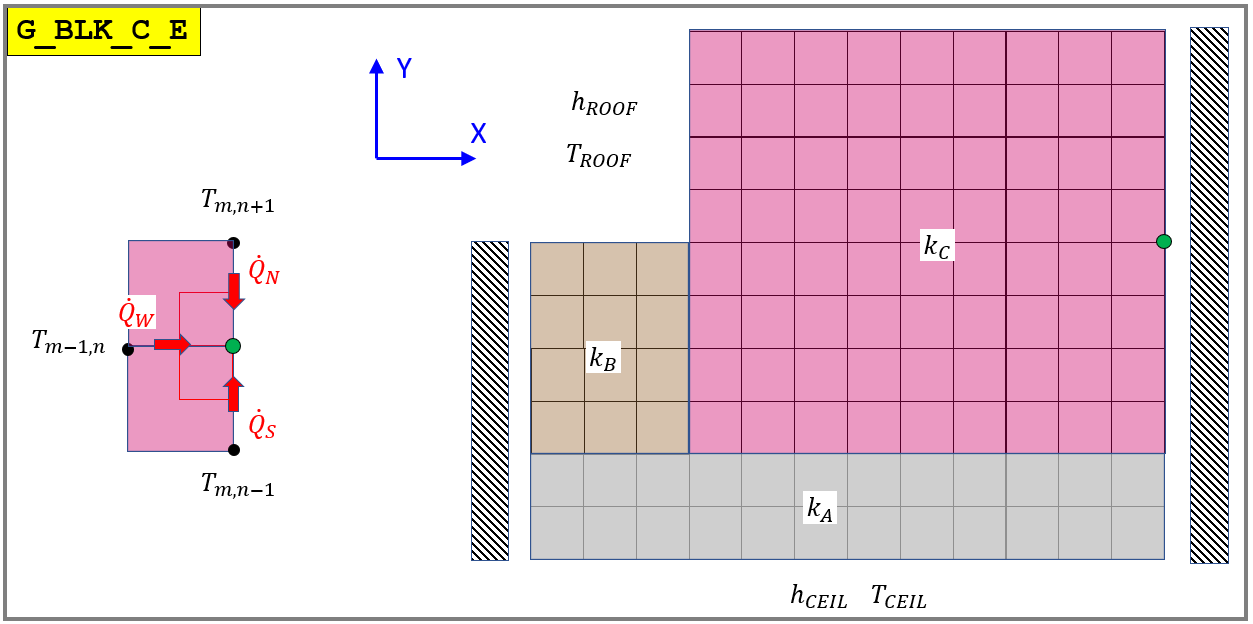

function [A, b, x]  = LOC_G_BLK_C_E()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",     "S_0"   , "E_0", "W_0"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_HALF",  "S_HALF", "E_0", "W_FULL"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_C,       k_C,    sym(0),    k_C);
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

# 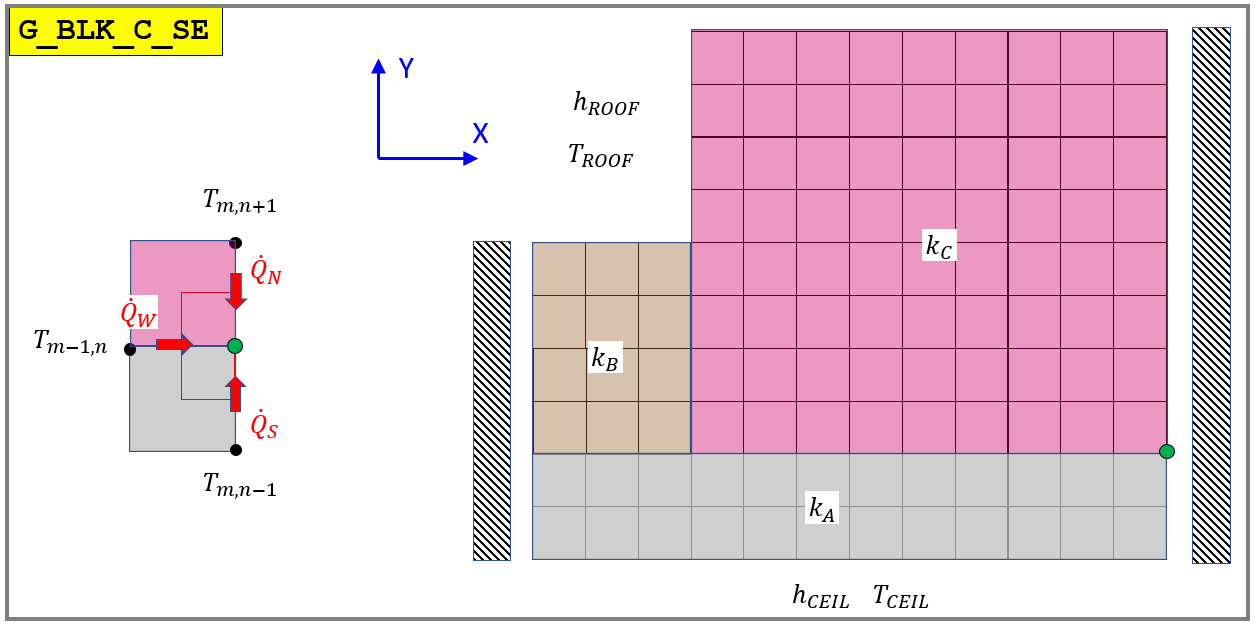

function [A, b, x]  = LOC_G_BLK_C_SE()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",     "S_0"   , "E_0", "W_0"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_HALF",  "S_HALF", "E_0", "W_FULL"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_C,       k_A,    sym(0),    k_C);
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

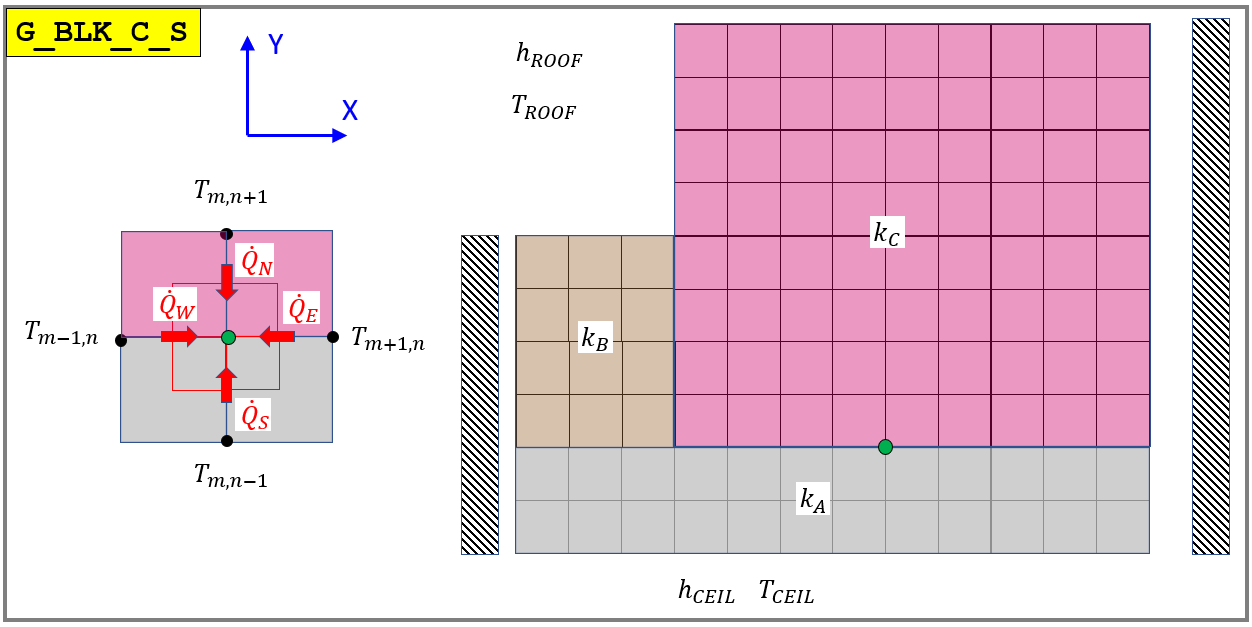

function [A, b, x]  = LOC_G_BLK_C_S()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",     "S_0"   , "E_0",    "W_0"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_FULL",  "S_FULL", "E_FULL", "W_FULL"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_C,       k_A,      k_C,    k_C);
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

# **A-block node types**

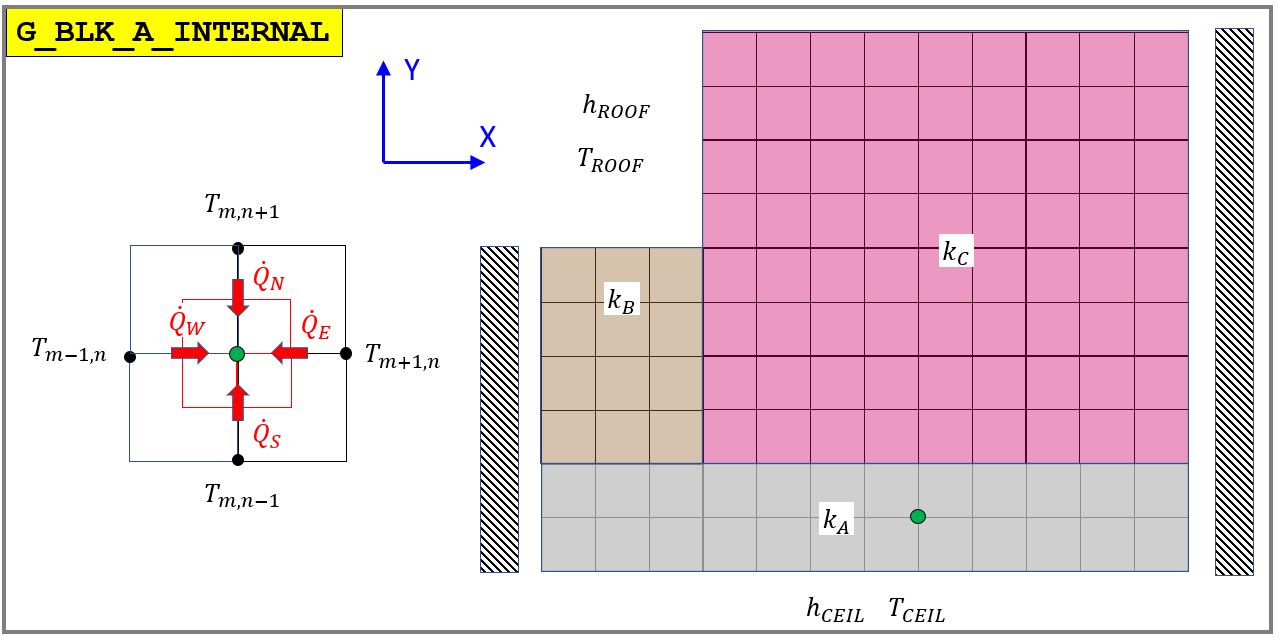

function [A, b, x]  = LOC_G_BLK_A_INTERNAL()
  %Load symbolic symbols
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",    "S_0"   , "E_0"   , "W_0"); % Convection Areas
  [A_N , A_S , A_E , A_W ] = LOC_get_A_NSEW("N_FULL", "S_FULL", "E_FULL", "W_FULL"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_A ,     k_A,      k_A,      k_A);
  
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc_BLK_A(A_cond, A_conv, k, d);    
end
%%%
%%
%

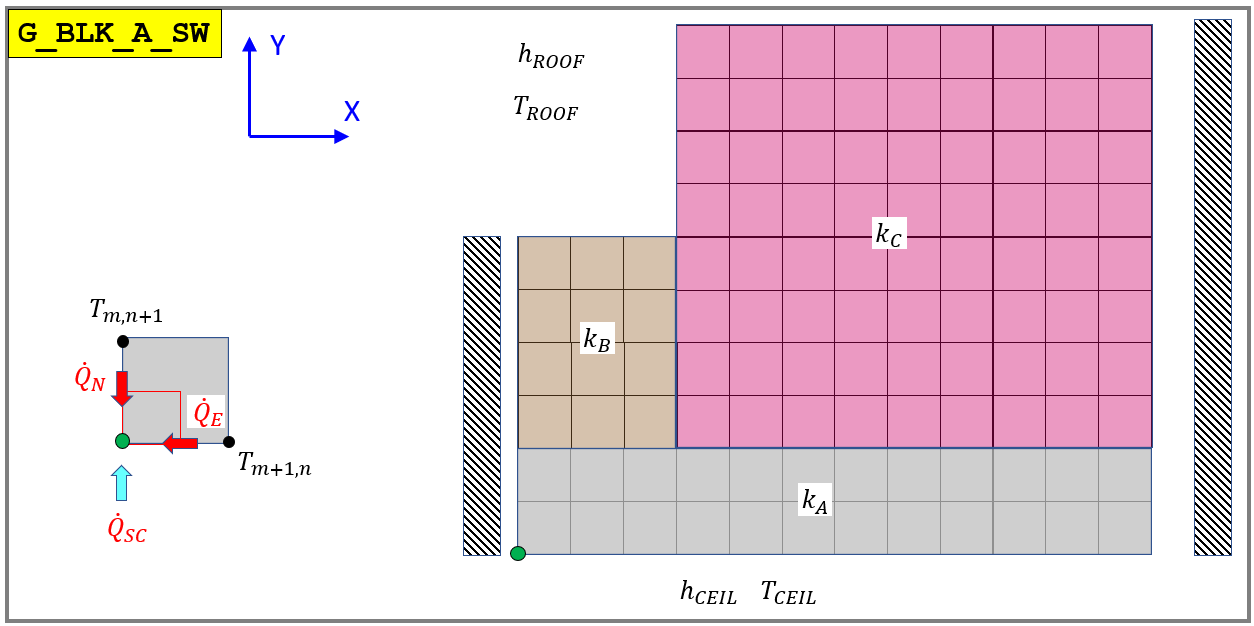

function [A, b, x]  = LOC_G_BLK_A_SW()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",     "S_HALF", "E_0",    "W_0"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_HALF",  "S_0",    "E_HALF", "W_0"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_A,       sym(0),   k_A,    sym(0));
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc_BLK_A(A_cond, A_conv, k, d);    
end
%%%
%%
%

# 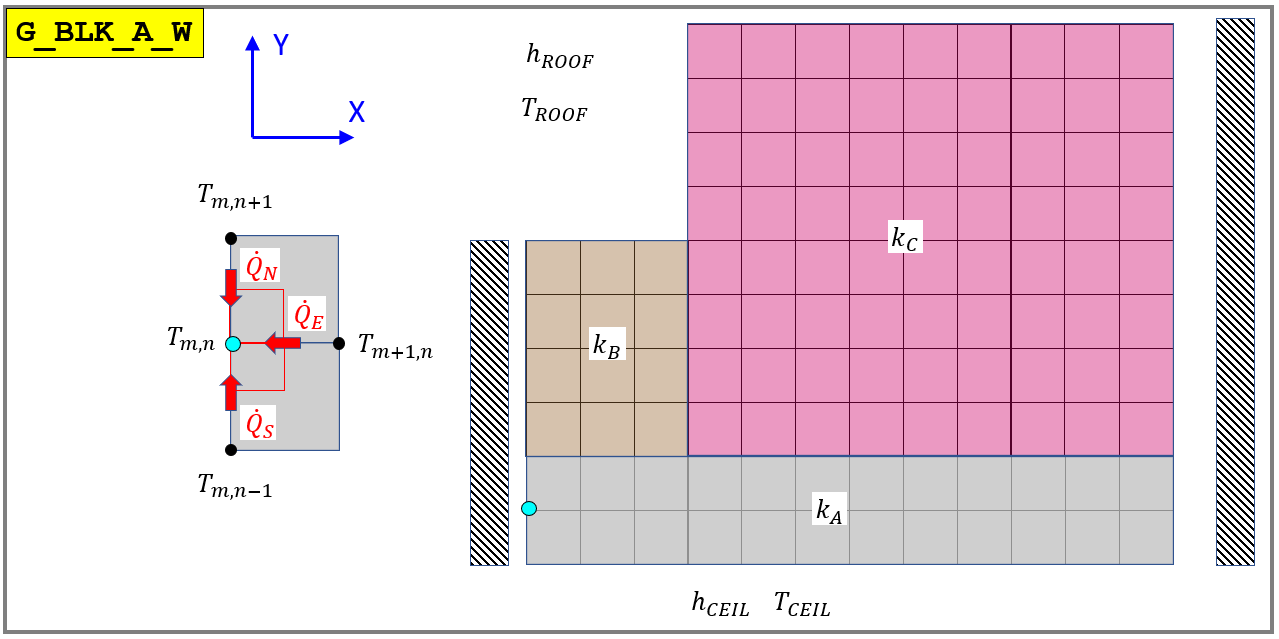

function [A, b, x]  = LOC_G_BLK_A_W()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",    "S_0"   , "E_0"   , "W_0"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_HALF", "S_HALF", "E_FULL", "W_0"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_A,      k_A,      k_A,     sym(0));
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc_BLK_A(A_cond, A_conv, k, d);    
end
%%%
%%
%

# 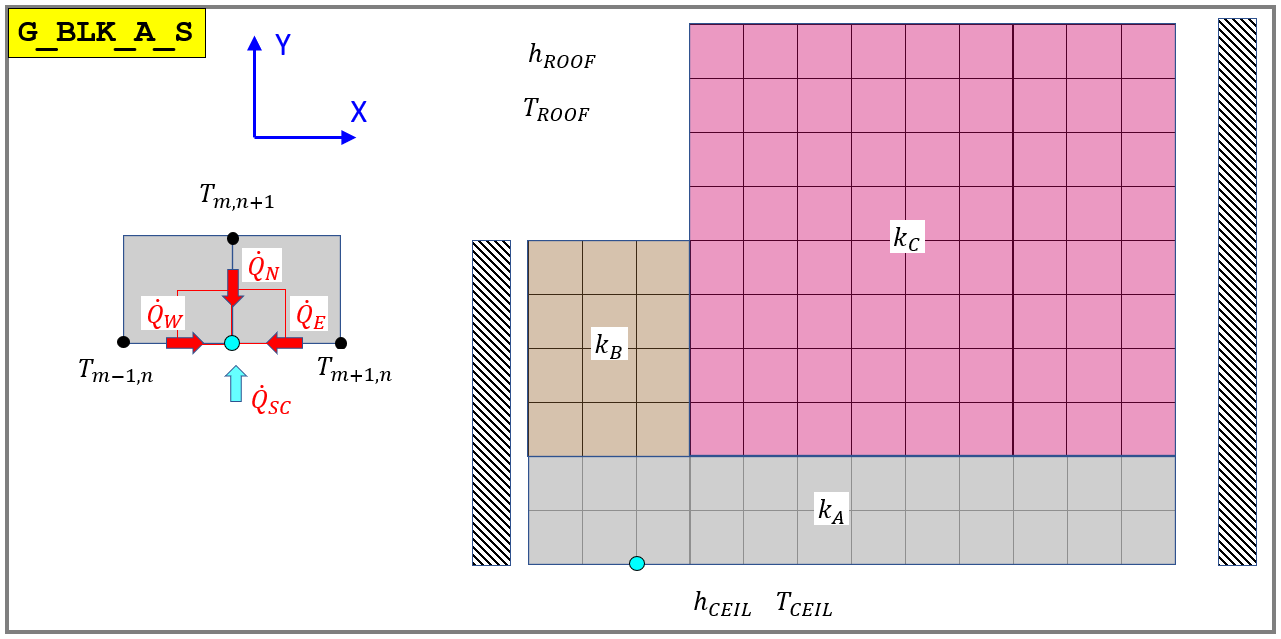

function [A, b, x]  = LOC_G_BLK_A_S()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",    "S_FULL",  "E_0",    "W_0"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_FULL", "S_0",     "E_HALF", "W_HALF"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_A,      sym(0),     k_A,     k_A);
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc_BLK_A(A_cond, A_conv, k, d);    
end
%%%
%%
%

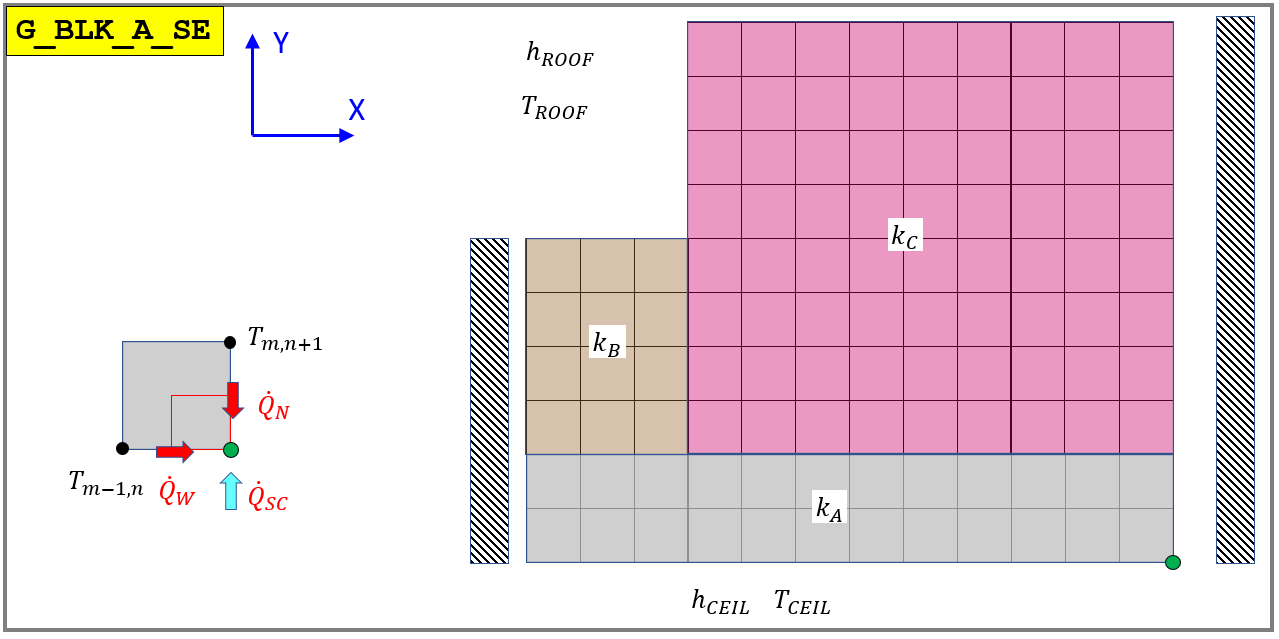

function [A, b, x]  = LOC_G_BLK_A_SE()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",    "S_HALF",  "E_0",    "W_0"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_HALF", "S_0",     "E_0",    "W_HALF"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_A,      sym(0),   sym(0),     k_A);
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc_BLK_A(A_cond, A_conv, k, d);    
end
%%%
%%
%

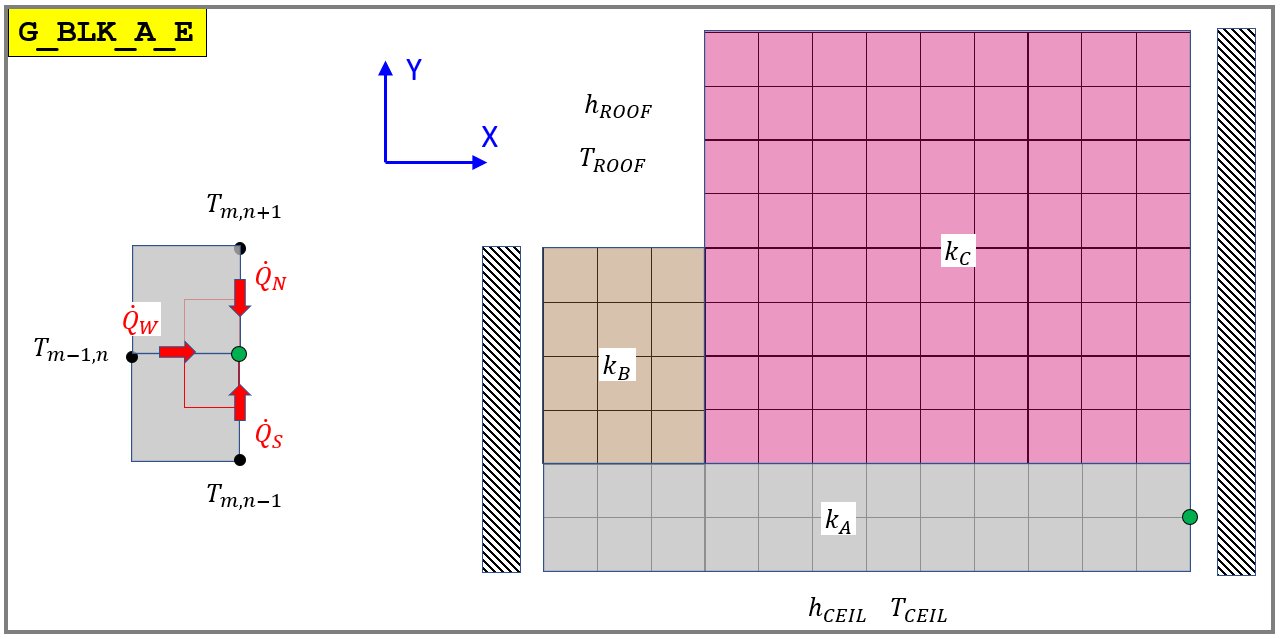

function [A, b, x]  = LOC_G_BLK_A_E()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",    "S_0",    "E_0",    "W_0"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_HALF", "S_HALF",  "E_0",    "W_FULL"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_A,      k_A,      sym(0),     k_A);
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc_BLK_A(A_cond, A_conv, k, d);    
end
%%%
%%
%